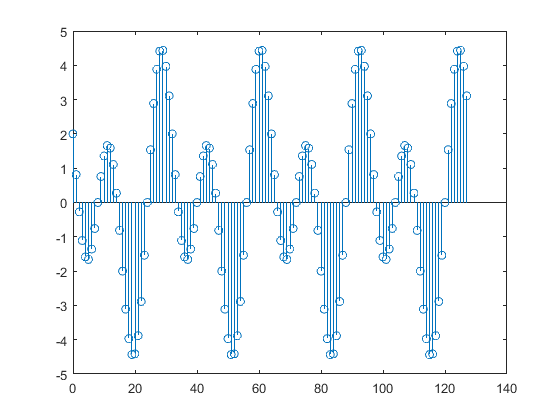

%Filtrado lineal en el dominio frecuencial
%Filtro pasabajos ideal
N=128;
n= 0:N-1;
xn=2*cos(2*pi*1/32*n)-3*sin(2*pi*1/16*n);
figure('Name','señal x(n)')
stem(n,xn)

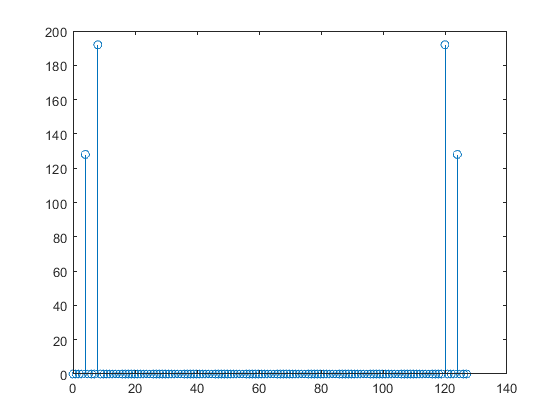

%Espectro de x(n) usando fft
xk=fft(xn);
figure('Name','Espectro (magnitud)')
stem(n,abs(xk))

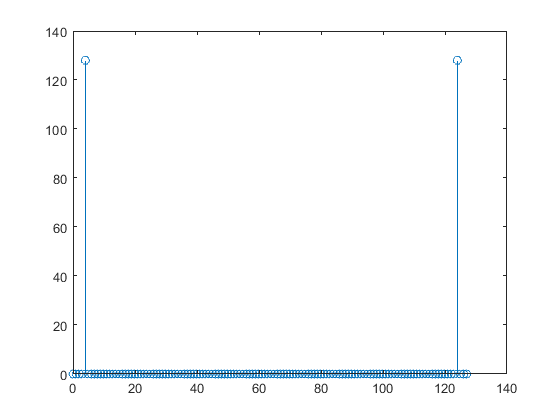

%Filtrado pasabajos ideal wc=1/20
wc=1/20;
wct=floor(wc*N);
xkf=xk;
for i=1:N+1
if (i>wct) && (i<N+2-wct)
xkf(i)=0;
end
end
figure('Name','Espectro (magnitud) filtrado')
stem(n,abs(xkf))

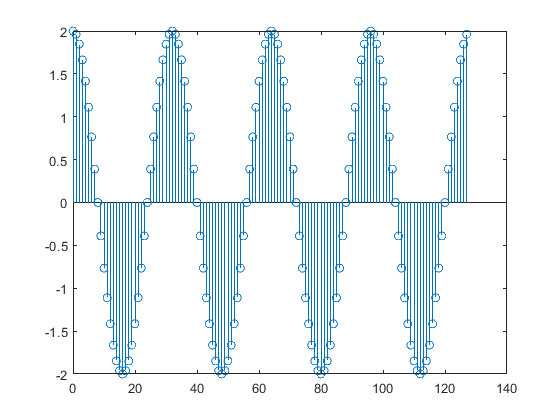

% Reconstrucción señal filtrada
xnf=real(ifft(xkf));
figure('Name','Señal x(n) filtrada');
stem(n,xnf)